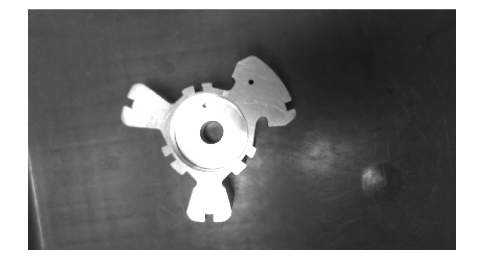

original = rgb2gray(org);
distorted = rgb2gray(dist);
imshow(original);

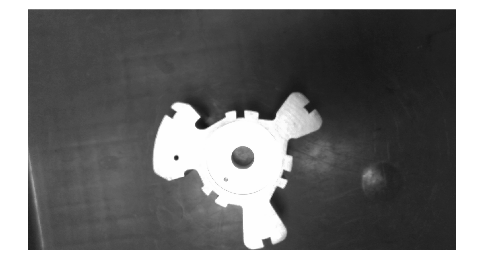

imshow(distorted);


ptsOriginal = detectSURFFeatures(original);
ptsDistorted = detectSURFFeatures(distorted);

[featuresOriginal,validPtsOriginal] = extractFeatures(original,ptsOriginal);
[featuresDistorted,validPtsDistorted] = extractFeatures(distorted,ptsDistorted);
indexPairs = matchFeatures(featuresOriginal,featuresDistorted);

matchedOriginal = validPtsOriginal(indexPairs(:,1));
matchedDistorted = validPtsDistorted(indexPairs(:,2));

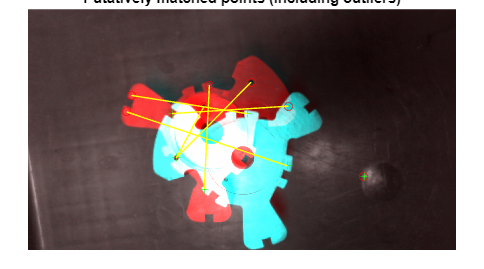

figure
showMatchedFeatures(original,distorted,matchedOriginal,matchedDistorted);
title('Putatively matched points (including outliers)');

[tform, inlierIdx] = estgeotform2d(matchedDistorted,matchedOriginal,'similarity');
inlierDistorted = matchedDistorted(inlierIdx,:);
inlierOriginal = matchedOriginal(inlierIdx,:);

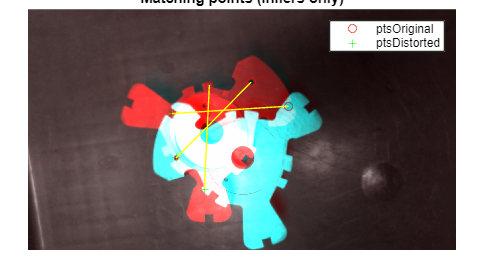

figure;
showMatchedFeatures(original,distorted,inlierOriginal,inlierDistorted);
title('Matching points (inliers only)');
legend('ptsOriginal','ptsDistorted');

invTform = invert(tform);
Ainv = invTform.A;

ss = Ainv(1,2);
sc = Ainv(1,1);
scaleRecovered = hypot(ss,sc);
disp(['Recovered scale: ', num2str(scaleRecovered)])

Recovered scale: 1.0001



% Recover the rotation in which a positive value represents a rotation in
% the clockwise direction.
thetaRecovered = atan2d(-ss,sc);
disp(['Recovered theta: ', num2str(thetaRecovered)])

Recovered theta: -128.0134


disp(['Scale: ' num2str(invTform.Scale)])

Scale: 1.0001


disp(['RotationAngle: ' num2str(invTform.RotationAngle)])  

RotationAngle: -128.0134
